# Thermal Modeling

First, the model Thermal distributions are modeled based on Figure 4 in K.H. Horstmann "New model Thermal distributions and their influence on interpretation of gliders"

clc
clear all

% Thermal distributions based at a radius of 60 m
L_Dmax = 46.5; % L/D max
A = 29; % Aspect Ratio
e = .9; % Oswald efficiency factor
phi = (pi ./ 180) .* [30 35 40 45 50]; % Roll angle in rad Per Horstmann from experience: 45deg-49deg good for tight thermals, 29deg-34deg goood for wide thermals
V_k = [60 70 80 90 100 110 120 130 140];
W2S = [250 300 350 400 450 500 550 600]; % Wing loading N/m^2
r = 30:325; % Turn radius m
r = 10:325; % Turn radius m
g = 9.81; % Acceleration due to gravity m/s^2
T_nonstand = 10; % Temperature of non standard day
rho_1 = 1.225; % Sea level density kg/m^3
[T, a, P, rho_alt] = atmosisa(convlength(3000, 'ft', 'm')); % Standard Density kg/m^3 at altitude


% Calculate rho at altitude at ISA + 10C
T_1 = 15 + 273.15; % Temp at sea level K
T_2  = T_1 + T_nonstand;
rho_2 = rho_1 * T_1 / T_2; % Density kg/m^3 at ISA + T_nonstand
sigma_nonstand = rho_2/rho_1; % Density ratio at ISA + T_nonstand
sigma_altstand = rho_alt/rho_1;
sigma_altnonstand = sigma_altstand * sigma_nonstand;
rho = rho_alt * sigma_nonstand;

% Calculate C_D0
C_Lmax = (pi * A * e) / (2 * L_Dmax); % Maximum lift coefficient
C_Dmax = C_Lmax/L_Dmax; % Maximum drag coefficient
C_D0 = C_Dmax / 2; % Parasite drag coefficient
C_D0 = .0044 + .008

C_D0 = 0.0124

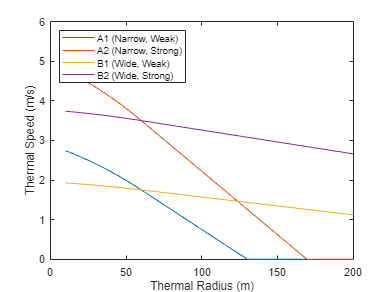



V_T = HorstmannThermal(r);

figure
plot(r,V_T(1,:))
hold on
plot(r,V_T(2,:))
plot(r,V_T(3,:))
plot(r,V_T(4,:))

xlim([0,200])
ylim ([0,6])

xlabel("Thermal Radius (m)")
ylabel("Thermal Speed (m/s)")
legend('A1 (Narrow, Weak)','A2 (Narrow, Strong)','B1 (Wide, Weak)','B2 (Wide, Strong)', Location="northwest")

hold off



% Sink Rate
% Use various bank angles, wing loadings, and air speeds



% Find sink rates at different wing loadings
V_sc = Vsinkrate(C_Dmax, C_Lmax, r, g, rho, W2S); % Sink rate m/s

% Find sink rates at different airspeeds with fixed angle and wing loading
V_scvk = Vsinkratevk(C_Dmax, C_Lmax, r, g, phi(1,5), V_k, rho, W2S(1,1));

% Find sink rates at different angles with fixed airspeed and wing loading
V_scphi = Vsinkratephi(C_Dmax, C_Lmax, r, g, phi, V_k(1,3), rho, W2S(1,1));

% Find sink rates at different wing loadings with fixed airspeed and angle

V_scW2S = VsinkrateW2S(C_Dmax, C_Lmax, r, g, phi(1,5), V_k(1,1), rho, W2S);


% Find sink rates at optimal roll angles in different thermals
% Note that phi angles are based on range given from Horstmann, larger
% angles for tight thermals, smaller for wide thermals
V_sc_phi = Vsinkrate_phi(C_Dmax, C_Lmax, phi, rho, W2S); %Sink rates at different wing loadings (rows) and at different roll angles (columns)

% Find locations of where the sink rates from optimal roll angles are found within 1.5%
% See livesript output and unsurpress as needed. Each set of outputs corresponds to one phi angle.
% Each loop should have 5 f outputs, first corresponding to phi(1,1) last phi(1,5)
for l = 1:size(V_sc_phi,1)
    for k = 1:length(phi)
        f = find(V_sc(l,:) >= V_sc_phi(1,k) & V_sc(l,:) <= V_sc_phi(l,k) + 0.015*V_sc_phi(l,k));
    end
end

% Note: average position listed, if between positions, rounded up
r_phi_pos = [105, 88, 76, 66, 59;         % Position of angle on r vector
             132, 112, 97, 86, 77;
             158, 135, 118, 105, 94;
             185, 159, 139, 124, 112;
             212, 182, 160, 143, 130;
             239, 205, 181, 162, 148;
             265, 229, 202, 181, 165;
             292, 252, 223, 200, 183];

% Find climb rates in different thermals for various wing loadings 

[V_ca1, V_ca2, V_cb1, V_cb2] = Vclimbspeed(V_T, V_sc);


figure;
plot(r,V_sc(1,:))

hold on
 for i = 2:length(W2S)
     plot(r,V_sc(i,:));
 end

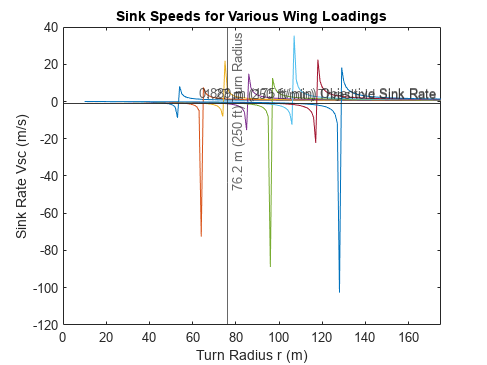


title('Sink Speeds for Various Wing Loadings')
%ylim([0,4])
xlim([0,175])
xlabel('Turn Radius r (m)')
ylabel('Sink Rate Vsc (m/s)')
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
%legend('A1','A2','B1','B2', Location="southwest")
hold off



% Plot chosen sink rate
% Note that a middle wing loading was chosen as it is roughly an average
% of the range sailplane wingloadings are typically
figure;
plot(r,V_sc(5,:))

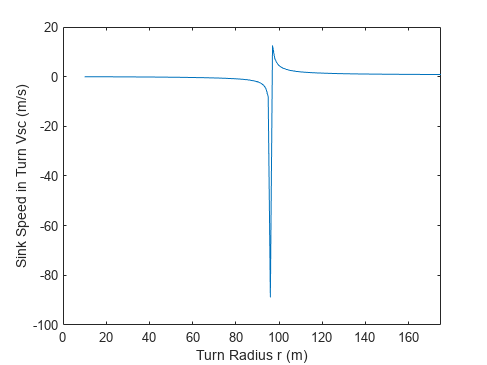

xlim([0,175])
xlabel('Turn Radius r (m)')
ylabel('Sink Speed in Turn Vsc (m/s)')
hold off



% Plot climb speed for optimum sink rate wing loading (found in V_sc vs R)

figure;
plot(r,V_ca1(8,:))

hold on

plot(r,V_ca2(8,:))

plot(r,V_cb1(8,:))

plot(r,V_cb2(8,:))

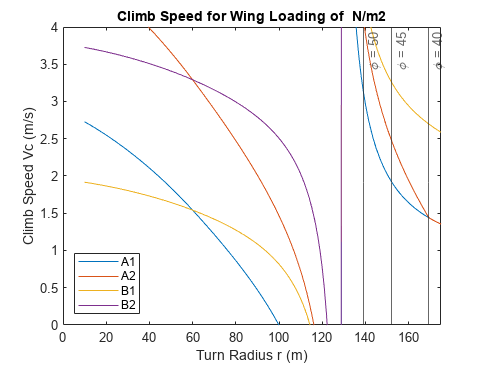


title('Climb Speed for Wing Loading of  N/m2')
ylim([0,4])
xlim([0,175])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed Vc (m/s)')
xline(r(1,r_phi_pos(5,1)), "-","\phi = 30")
xline(r(1,r_phi_pos(5,2)), "-","\phi = 35")
xline(r(1,r_phi_pos(5,3)), "-","\phi = 40")
xline(r(1,r_phi_pos(5,4)), "-","\phi = 45")
xline(r(1,r_phi_pos(5,5)), "-","\phi = 50")

%yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
%yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
legend('A1','A2','B1','B2', Location="southwest")
hold off



figure;
plot(r,V_ca1(1,:))

hold on

plot(r,V_ca2(1,:))

plot(r,V_cb1(1,:))

plot(r,V_cb2(1,:))

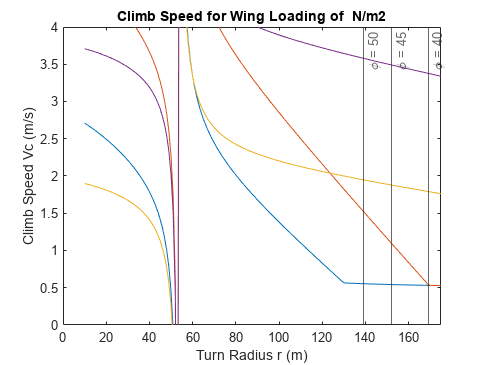


title('Climb Speed for Wing Loading of  N/m2')
ylim([0,4])
xlim([0,175])
xlabel('Turn Radius r (m)')
ylabel('Climb Speed Vc (m/s)')
xline(r(1,r_phi_pos(5,1)), "-","\phi = 30")
xline(r(1,r_phi_pos(5,2)), "-","\phi = 35")
xline(r(1,r_phi_pos(5,3)), "-","\phi = 40")
xline(r(1,r_phi_pos(5,4)), "-","\phi = 45")
xline(r(1,r_phi_pos(5,5)), "-","\phi = 50")



% plot the average cross country speed
V_c = V_ca1(8,:)

V_c = 1.0e+02 *

   0.0273 - 0.0001i   0.0271 - 0.0001i   0.0269 - 0.0002i   0.0268 - 0.0002i   0.0266 - 0.0002i   0.0264 - 0.0002i   0.0262 - 0.0002i   0.0261 - 0.0003i   0.0259 - 0.0003i   0.0257 - 0.0003i   0.0255 - 0.0003i   0.0253 - 0.0004i   0.0251 - 0.0004i   0.0249 - 0.0004i   0.0247 - 0.0004i   0.0245 - 0.0005i   0.0243 - 0.0005i   0.0241 - 0.0005i   0.0239 - 0.0006i   0.0236 - 0.0006i   0.0234 - 0.0006i   0.0232 - 0.0007i   0.0230 - 0.0007i   0.0227 - 0.0007i   0.0225 - 0.0008i   0.0223 - 0.0008i   0.0220 - 0.0009i   0.0218 - 0.0009i   0.0216 - 0.0009i   0.0213 - 0.0010i   0.0211 - 0.0010i   0.0208 - 0.0011i   0.0206 - 0.0011i   0.0203 - 0.0011i   0.0200 - 0.0012i   0.0198 - 0.0012i   0.0195 - 0.0013i   0.0192 - 0.0013i   0.0190 - 0.0014i   0.0187 - 0.0014i   0.0184 - 0.0015i   0.0181 - 0.0015i   0.0178 - 0.0016i   0.0175 - 0.0017i   0.0173 - 0.0017i   0.0170 - 0.0018i   0.0167 - 0.0018i   0.0164 - 0.0019i   0.0160 - 0.0020i   0.0157 - 0.0020i


V_avg = Vavgfsd(V_ca1(8,:), C_D0, A, e, rho, W2S, C_L)

Unrecognized function or variable 'C_L'.






% figure;
% 
% subplot(2,2,1)
% plot(r,V_ca1(1,:))
% hold on
% 
% plot(r,V_ca2(1,:))
% plot(r,V_cb1(1,:))
% plot(r,V_cb2(1,:))
% 
% title('Climb Speed for Wing Loading of 250 N/m^2')
% ylim([0,4])
% xlabel('Turn Radius r (m)')
% ylabel('Climb Speed V_c (m/s)')
% xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
% yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
% yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
% %legend('A1','A2','B1','B2', Location="southwest")
% hold off
% 
% subplot(2,2,2)
% plot(r,V_ca1(2,:))
% hold on
% 
% plot(r,V_ca2(2,:))
% plot(r,V_cb1(2,:))
% plot(r,V_cb2(2,:))
% 
% title('Climb Speed for Wing Loading of 300 N/m^2')
% ylim([0,3.75])
% xlabel('Turn Radius r (m)')
% ylabel('Climb Speed V_c (m/s)')
% xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
% yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
% yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
% hold off
% 
% subplot(2,2,3)
% plot(r,V_ca1(3,:))
% hold on
% 
% plot(r,V_ca2(3,:))
% plot(r,V_cb1(3,:))
% plot(r,V_cb2(3,:))
% 
% title('Climb Speed for Wing Loading of 350 N/m^2')
% ylim([0,3.75])
% xlabel('Turn Radius r (m)')
% ylabel('Climb Speed V_c (m/s)')
% xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
% yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
% yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
% hold off
% 
% subplot(2,2,4)
% plot(r,V_ca1(4,:))
% hold on
% 
% plot(r,V_ca2(4,:))
% plot(r,V_cb1(4,:))
% plot(r,V_cb2(4,:))
% 
% title('Climb Speed for Wing Loading of 400 N/m^2')
% ylim([0,3.5])
% xlabel('Turn Radius r (m)')
% ylabel('Climb Speed V_c (m/s)')
% xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
% yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
% yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
% hold off
% 
% figure;
% 
% subplot(2,2,1)
% plot(r,V_ca1(5,:))
% hold on
% 
% plot(r,V_ca2(5,:))
% plot(r,V_cb1(5,:))
% plot(r,V_cb2(5,:))
% 
% title('Climb Speed for Wing Loading of 450 N/m^2')
% ylim([0,3.5])
% xlabel('Turn Radius r (m)')
% ylabel('Climb Speed V_c (m/s)')
% xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
% yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
% yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
% hold off
% 
% subplot(2,2,2)
% plot(r,V_ca1(6,:))
% hold on
% 
% plot(r,V_ca2(6,:))
% plot(r,V_cb1(6,:))
% plot(r,V_cb2(6,:))
% 
% title('Climb Speed for Wing Loading of 500 N/m^2')
% ylim([0,3.5])
% xlabel('Turn Radius r (m)')
% ylabel('Climb Speed V_c (m/s)')
% xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
% yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
% yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
% hold off
% 
% subplot(2,2,3)
% plot(r,V_ca1(7,:))
% hold on
% 
% plot(r,V_ca2(7,:))
% plot(r,V_cb1(7,:))
% plot(r,V_cb2(7,:))
% 
% title('Climb Speed for Wing Loading of 550 N/m^2')
% ylim([0,3.5])
% xlabel('Turn Radius r (m)')
% ylabel('Climb Speed V_c (m/s)')
% xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
% yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
% yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")
% hold off
% 
% Vavg = Vavgfsd()
